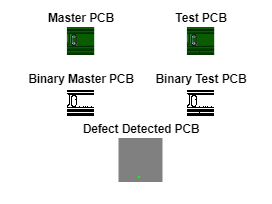

PATH = "PCB/";
index = 0;

master = imread(PATH + "master_" + index + ".jpg");
test = imread(PATH + "test_" + index + ".jpg");

%master = imresize(master, [257 190]);
%test = imresize(test, [257 190]);

% master_gray = rgb2gray(master);
% test_gray = rgb2gray(test);

binary_master = convert2binary(master);
binary_test = convert2binary(test);

subtracted_1 = imsubtract(binary_master, binary_test);
subtracted_2 = imsubtract(binary_test, binary_master);
subtracted_result = imfuse(subtracted_1, subtracted_2, 'diff');

subplot(3,2,1), imshow(master); title('Master PCB');
subplot(3,2,2), imshow(test); title('Test PCB');

subplot(3,2,3), imshow(binary_master); title('Binary Master PCB');
subplot(3,2,4), imshow(binary_test); title('Binary Test PCB');

subplot(3,2,[5 6]), imshow(subtracted_result); title('Defect Detected PCB');

function [binary] = convert2binary(original)
    [x, y, z] = size(original);

    if z==3
         original = rgb2gray(original);
    end

    original=double(original);

    sum = 0;
    for i = 1:x
        for j = 1:y
            sum = sum + original(i, j);
        end
    end

    threshold = sum / (x * y);
    binary = zeros(x, y);

    for i = 1:x
        for j = 1:y
            if original(i, j) >= threshold
                binary(i, j) = 1;
            else
                binary(i, j) = 0;
            end
        end
    end
end
